# Manusscript for presenting

This document is a modified version of the manusscript in Swedish (see generic_polynomial_interpolation.mlx) which can be shown during the live video to

# Exempel 1

## Generell polynominterpolation, samma exempel som i videon

Givet datasetet nedan, konstruera ett interpolationspolynom som går genom punkterna i datasetet.


$$\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right)$$


**Utseende av variabler**

x = [2; 4; 6];
y = [3.2; 2; 1.23];

Motsvarar matriserna


$$\vec x=\pmatrix{2&4&6},
\vec y = \pmatrix{3.2&2&1.23}$$
 

*MATLAB (utan inbyggda funktioner)*

**Framtagning av matriser för polynominterpolation**

Låt oss tillta på en enda punkt först, och låt oss vara generella och kalla den för $\left(x_1 ,y_1 \right)$. Om vi infogar $x_1 ,y_1$ i den allmäna ekvationen för ett andragradspolynom $y=c_1 x^2 +c_2 x+c_3$ får vi:

$y_1 =c_1 {x_1 }^2 +c_2 x_1 +c_3$ vilket kan skrivas på matrisform som: $\underbrace{\pmatrix{x_1^2&x_1&1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1}}_{\vec b}$


$$\underbrace{\pmatrix{x_1^2&x_1&1\cr x_2^2&x_2& 1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1\cr y_2}}_{\vec b}$$


Vi har tre punkter i vårt exempel, så den slutliga "allmäna" matrisen skulle bli enligt nedan:


$$\underbrace{\pmatrix{x_1^2&x_1&1\cr x_2^2&x_2& 1\cr x_3^2&x_3& 1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2\cr c_3}}_{\vec x}=\underbrace{\pmatrix{y_1\cr y_2\cr y_3}}_{\vec b}$$


För att minnas hur varje rad i matrisen ska se ut, låt mig fokusera på en rad i den fullständiga interpolationsmatrisen som vi nyss tog fram ovan.

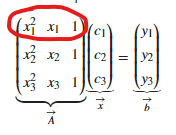

Låt oss också notera att det enda som skiljer raderna åt i A-matrisen är x-värdena.

Så generellt kan en rad i matrisen uttryckas som:


$$\matrix{x_i^2&x_i&1}$$


# Exempel 2

## Minsta kvadratmetoden, samma exempel som i videon

Givet datasetet nedan, konstruera ett minstakvadratanpassat andragradspolynom till datapunkterna.


$$\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right),\left(-6,1\ldotp 23\right),\left(-4,2\right),\left(-2,3\ldotp 2\right),\left(0,4\right),\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right),\left(8,0\ldotp 8\right),\left(10,0\ldotp 55\right)$$


Inget att visa upp

# Exempel 3

## Centrering, samma exempel som i videon

Givet datasetet nedan, konstruera ett interpolationspolynom som går genom punkterna i datasetet.


$$\left(1568,20\right),\left(1570,24\right),\left(1572,22\right)$$


**Skillnad i generisk polynomekvation utan resp. med centering **

$y=c_1 x^2 +c_2 x+c_3$. VS $y=c_1 \left({\left.x-m\right)}^2 +c_2 \left(x-m\right)+c_3 \right.$

*MATLAB (inbygda funktioner)*

**MATLABs "mu"-vektor**

 "mu" är en vektor med två värden, $\mu =\left(\mu_1 ,\mu_2 \right)$ .

 MATLAB kommer nämligen göra följande: ändra dina infograde x-värden genom att ändra de enligt formeln $\vec x=\frac{\vec x-\mu_1}{\mu_2}$ där $\left(\mu_1 ,\mu_2 \right)$ är två magiska tal som MATLAB räknat ut.

Om du vill veta mer om de hänvisar jag till MATLABs dokumentation.

# Exempel 4

## Splines, samma exempel som i videon

Givet datasetet nedan, konstruera **linjära och kubiska** splines anpassade till datapunkterna.


$$\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right),\left(-6,1\ldotp 23\right),\left(-4,2\right),\left(-2,3\ldotp 2\right),\left(0,4\right),\left(2,3\ldotp 2\right),\left(4,2\right),\left(6,1\ldotp 23\right),\left(8,0\ldotp 8\right),\left(10,0\ldotp 55\right)$$


*MATLAB, inbyggda funktioner*

Inget att visa upp

*MATLAB (utan inbyggda funktioner)*

**Ekvationssystem för två första punkterna**

De två första punkterna $\left(-10,0\ldotp 55\right),\left(-8,0\ldotp 8\right)$.

Allmäna formeln för ett förstagradspolynom är: $y=c_1 x+c_2$ där c1 och c2 ofta kallas för k och m.

**Ekvationssystem för två första punkterna**

Ekvationssystemet som ska lösas för att interpolera mellan dessa två punkter är:


$$\left\lbrace \begin{array}{ll}
0\ldotp 55=-10c_1 +c_2  & \\
0\ldotp 8=-8c_1 +c_2  & 
\end{array}\right.$$


Vi kan skriva om det på matrisform som


$$\underbrace{\pmatrix{-10&1\cr-8&1}}_{\vec A}\underbrace{\pmatrix{c_1\cr c_2}}_{\vec x}=\underbrace{\pmatrix{0.55\cr 0.8}}_{\vec b}$$
